# CONTROL DISCRETO - PRACTICA 3 : Muestreo

**NOTA:** Se han eliminado los acentos debido a que la impresionen pdf no reconocia el caracter.

## Caso de estudio

Se  desea  estudiar  el  fenomeno  del  defecto  en  la  reconstruccion  de  una  señal  debido  a  un muestreo a una frecuencia demasiado baja.  Para ello se estudiara la siguiente **señal** : y(t) = Suma de tres señales seno, la 1ª tiene una amplitud de 0.7 y una frecuencia de 50Hz, la 2ª tiene una amplitud de 1 y una frecuencia de 120Hz, la 3ª (ruido) tiene una amplitud de 0.2 y una frecuencia de 1000Hz.

La señal original es la suma de dos señales sinusoidales una a 50Hz y otra a 120Hz. Se le añade ruido a 1kHz.

Las **frecuencias de muestreo** seran: 500 Hz, 800Hz  y 3000Hz.

## Tareas a realizar

- Declara en MATLAB la función continua f(t) del apartado anerior. Graficala y evalua la señal desde los 0s hasta los 0.03s

- Obten el espectro en frecuencia de la señal a una frecencia de muestreo de 500 Hz.

- Obten la representacion discreta de la funcion f(t), con un vector k de 1500 muestras a una frecuencia de muestreo de 500Hz. Haz lo mismo para cada uno de los tres componenetes. ¿Que tal son las representaciones?¿Se ha podido reconstruir la señal de maneda adecuada?

- Repite los anteiores dos puntos pero con las frecuencias de muestreo de 800Hz y 3000Hz. Establece una comparativa entre las representaciones de las tres componentes muestreadas con cada una de estas tres frecuencias de muestreo y tambien de la señal producto dela suma de dichas componentes, es decir f(t)).

***Nota: ***Por uniformidad, los graficos tendrán que ser representados de 0s a 0.03s.

## Funcion continua

Declaracion de la funcion continua

str = '@(t)0.7*sin(2*pi*50*t)+sin(2*pi*120*t)+0.2*sin(2*pi*1000*t)'

str = '@(t)0.7*sin(2*pi*50*t)+sin(2*pi*120*t)+0.2*sin(2*pi*1000*t)'

y = str2func(str)

y = function_handle with value:
    @(t)0.7*sin(2*pi*50*t)+sin(2*pi*120*t)+0.2*sin(2*pi*1000*t)


## Frecuencia 500 Hz

#### Ploteo de la funcion continua

figure(1);
subplot(2,1,1), fplot(y,[0,0.03]);
title('Señal con ruido');xlabel('tiempo (ms)');

#### Calculo de la Transformada de Fourier

Fs = 500;             % Frecuencia de muestreo;
Ts = 1/ Fs;           % Periodo de muestreo.
L = 1500;             % Longitud de la señal en muestras.
k = (0:L-1)*Ts;       % Vectorde tiempo discreto.
% Evalua la función con el vector discreto k.
Y=0.7*sin(2*pi*50*k)+sin(2*pi*120*k)+0.2*sin(2*pi*1000*k);          
k500 = k;                % Var guardad par aposteriormente utilizarla en las comparaciones

Realizamos la trasnformada de Fourier, mediante fft

Yf = 2*abs(fft(Y)/L);

Generar el eje x de la grafica del espectro.

f = Fs*linspace(0,1,L);

Graficar el** espectro** debajo de la señal continua

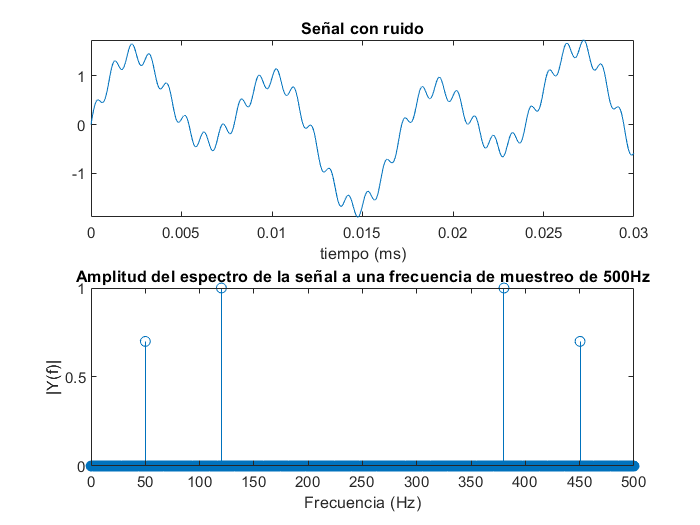

subplot(2,1,2);
stem(f,Yf);   % Podríamos poner plot, pero queremos representación discreta.
title('Amplitud del espectro de la señal a una frecuencia de muestreo de 500Hz') %valor absoluto
xlabel('Frecuencia (Hz)');ylabel('|Y(f)|')

#### Discretizar cada componente por separado, evaluandolas con el vector k.

y1 = str2func('@(k)0.7*sin(2*pi*50*k)');
Y1=y1(k);
y2 = str2func('@(k)sin(2*pi*120*k)');
Y2=y2(k);
y3 = str2func('@(k)0.2*sin(2*pi*1000*k)');
Y3=y3(k);

#### Grafica las tres componentes en continuo y en discreto, poniendo cada componente frecuencial en un gráfico nuevo que vaya debajo del anterior. 

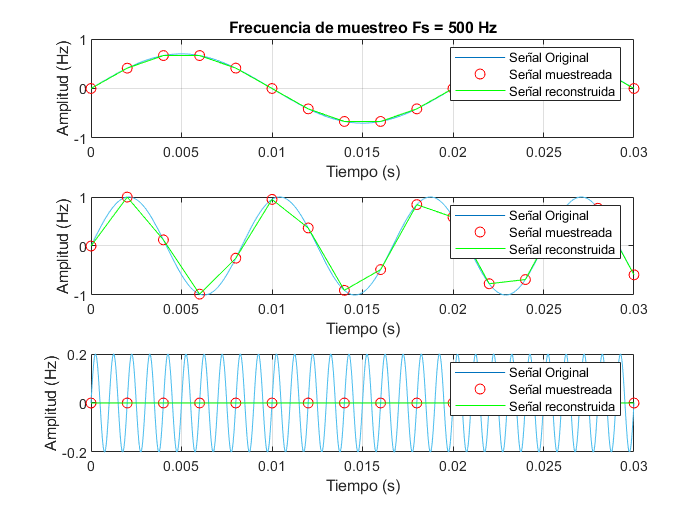

figure(2);
subplot(3,1,1); fplot(y1,[0,0.03]); hold on; 
plot(k,Y1,'ro'); plot(k,Y1,'g-'); axis([0 0.03 -1 1])
title('Frecuencia de muestreo Fs = 500 Hz')
legend('Señal Original','Señal muestreada','Señal reconstruida')
xlabel('Tiempo (s)'); ylabel('Amplitud (Hz)');
grid on

subplot(3,1,2); fplot(y2,[0,0.03]); hold on;
plot(k,Y2,'ro'); plot(k,Y2,'g-'); axis([0 0.03 -1 1])
legend('Señal Original','Señal muestreada','Señal reconstruida')
xlabel('Tiempo (s)'); ylabel('Amplitud (Hz)');
grid on

subplot(3,1,3); fplot(y3,[0,0.03]); hold on;
plot(k,Y3,'ro'); plot(k,Y3,'g-'); axis([0 0.03 -0.2 0.2])
legend('Señal Original','Señal muestreada','Señal reconstruida')
xlabel('Tiempo (s)'); ylabel('Amplitud (Hz)');
grid on

## Frecuencia 800 Hz

#### Ploteo de la funcion continua

figure(3);
subplot(2,1,1), fplot(y,[0,0.03]);
title('Señal con ruido');xlabel('tiempo (ms)');

#### Calculo de la Transformada de Fourier

Fs = 800;             % Frecuencia de muestreo;
Ts = 1/ Fs;           % Periodo de muestreo.
L = 1500;             % Longitud de la señal en muestras.
k = (0:L-1)*Ts;       % Vectorde tiempo discreto.
Y=0.7*sin(2*pi*50*k)+sin(2*pi*120*k)+0.2*sin(2*pi*1000*k);         % Evalua la función con el vector discreto k. 
k800 = k;                % Var guardad par aposteriormente utilizarla en las comparaciones

Realizamos la trasnformada de Fourier, mediante fft

Yf = 2*abs(fft(Y)/L);

Generar el eje x de la grafica del espectro.

f = Fs*linspace(0,1,L);

Graficar el espectro debajo de la señal continua

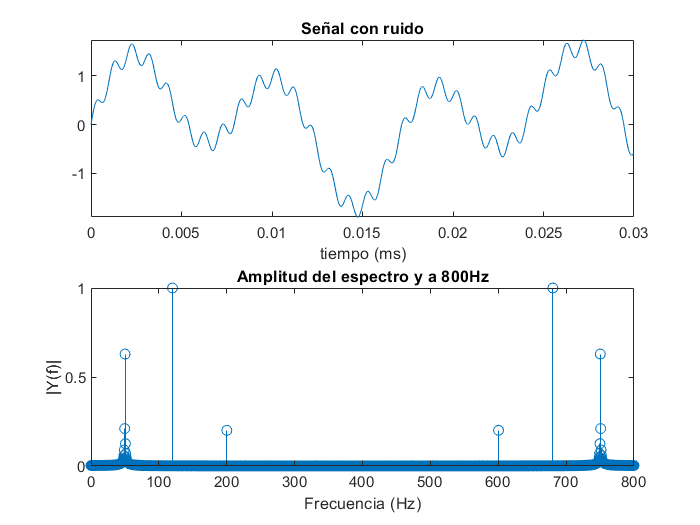

subplot(2,1,2);
stem(f,Yf);   % Podríamos poner plot, pero queremos representación discreta.
title('Amplitud del espectro y a 800Hz') %valor absoluto
xlabel('Frecuencia (Hz)');ylabel('|Y(f)|')

#### Discretizar cada componente por separado, evaluandolas con el vector k.

y4 = str2func('@(k)0.7*sin(2*pi*50*k)');
Y4=y4(k);
y5 = str2func('@(k)sin(2*pi*120*k)');
Y5=y5(k);
y6 = str2func('@(k)0.2*sin(2*pi*1000*k)');
Y6=y6(k);

#### Grafica las tres componentes en continuo y en discreto, poniendo cada componente frecuencial en un gráfico nuevo que vaya debajo del anterior. 

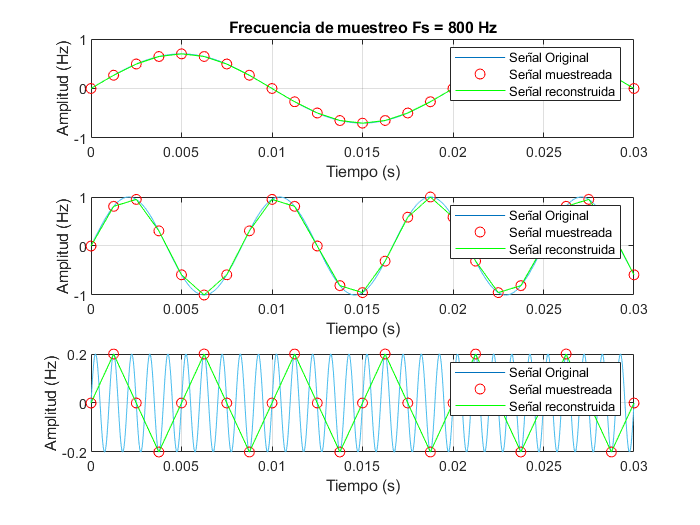

figure(4);
subplot(3,1,1); fplot(y4,[0,0.03]); hold on; 
plot(k,Y4,'ro'); plot(k,Y4,'g-'); axis([0 0.03 -1 1])
title('Frecuencia de muestreo Fs = 800 Hz')
legend('Señal Original','Señal muestreada','Señal reconstruida')
xlabel('Tiempo (s)'); ylabel('Amplitud (Hz)');
grid on

subplot(3,1,2); fplot(y5,[0,0.03]); hold on;
plot(k,Y5,'ro'); plot(k,Y5,'g-'); axis([0 0.03 -1 1])
legend('Señal Original','Señal muestreada','Señal reconstruida')
xlabel('Tiempo (s)'); ylabel('Amplitud (Hz)');

subplot(3,1,3); fplot(y6,[0,0.03]); hold on;
plot(k,Y6,'ro'); plot(k,Y6,'g-'); axis([0 0.03 -0.2 0.2])
legend('Señal Original','Señal muestreada','Señal reconstruida')
xlabel('Tiempo (s)'); ylabel('Amplitud (Hz)');

## Frecuencia 3000 Hz

#### Ploteo de la funcion continua

figure(5);
subplot(2,1,1), fplot(y,[0,0.03]);
title('Señal con ruido');xlabel('tiempo (ms)');

#### Calculo de la Transformada de Fourier

Fs = 3000;             % Frecuencia de muestreo;
Ts = 1/ Fs;           % Periodo de muestreo.
L = 1500;             % Longitud de la señal en muestras.
k = (0:L-1)*Ts;       % Vectorde tiempo discreto.
Y=0.7*sin(2*pi*50*k)+sin(2*pi*120*k)+0.2*sin(2*pi*1000*k);         % Evalua la función con el vector discreto k. 
k3000 = k;                % Var guardad par aposteriormente utilizarla en las comparaciones

Realizamos la trasnformada de Fourier, mediante fft

Yf = 2*abs(fft(Y)/L);

Generar el eje x de la grafica del espectro.

f = Fs*linspace(0,1,L);

Graficar el espectro debajo de la señal continua

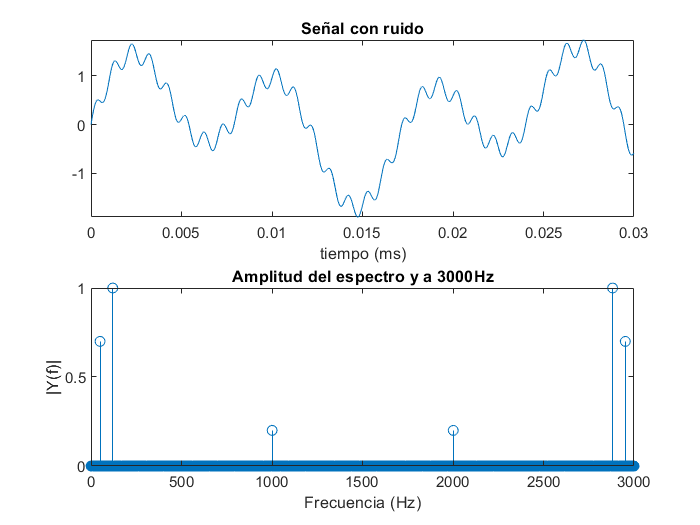

subplot(2,1,2);
stem(f,Yf);   % Podríamos poner plot, pero queremos representación discreta.
title('Amplitud del espectro y a 3000Hz') %valor absoluto
xlabel('Frecuencia (Hz)');ylabel('|Y(f)|')

#### Discretizar cada componente por separado, evaluandolas con el vector k.

y7 = str2func('@(k)0.7*sin(2*pi*50*k)');
Y7=y7(k);
y8 = str2func('@(k)sin(2*pi*120*k)');
Y8=y8(k);
y9 = str2func('@(k)0.2*sin(2*pi*1000*k)');
Y9=y9(k);

#### Grafica las tres componentes en continuo y en discreto, poniendo cada componente frecuencial en un gráfico nuevo que vaya debajo del anterior. 

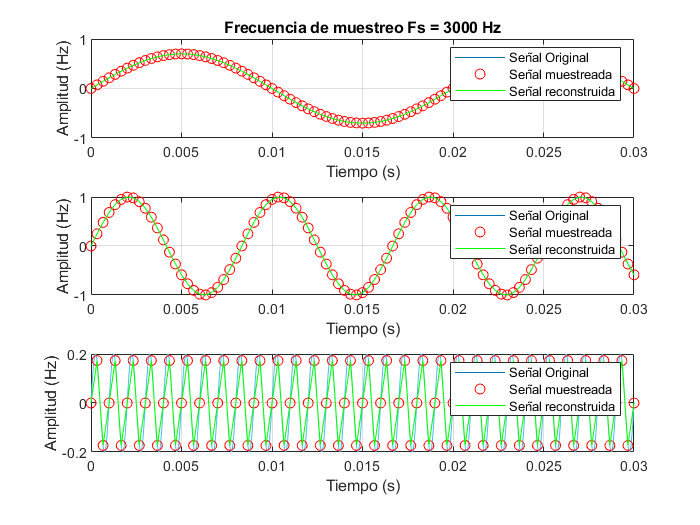

figure(6);
subplot(3,1,1); fplot(y7,[0,0.03]); hold on; 
plot(k,Y7,'ro'); plot(k,Y7,'g-'); axis([0 0.03 -1 1])
title('Frecuencia de muestreo Fs = 3000 Hz')
legend('Señal Original','Señal muestreada','Señal reconstruida')
xlabel('Tiempo (s)'); ylabel('Amplitud (Hz)');
grid on

subplot(3,1,2); fplot(y8,[0,0.03]); hold on;
plot(k,Y8,'ro'); plot(k,Y8,'g-'); axis([0 0.03 -1 1])
legend('Señal Original','Señal muestreada','Señal reconstruida')
xlabel('Tiempo (s)'); ylabel('Amplitud (Hz)');
grid on

subplot(3,1,3); fplot(y9,[0,0.03]); hold on;
plot(k,Y9,'ro'); plot(k,Y9,'g-'); axis([0 0.03 -0.2 0.2])
legend('Señal Original','Señal muestreada','Señal reconstruida')
xlabel('Tiempo (s)'); ylabel('Amplitud (Hz)');
grid on

## Comparaciones

A continuación se compararán las respuestas para las tres frecuencias de muestreo.

Amplitud del espectro de la señal:

**500 HZ**

Fs = 500;             % Frecuencia de muestreo;
Ts = 1/ Fs;           % Periodo de muestreo.
L = 1500;             % Longitud de la señal en muestras.
k = (0:L-1)*Ts;       % Vectorde tiempo discreto.
% Evalua la función con el vector discreto k.
Y=0.7*sin(2*pi*50*k)+sin(2*pi*120*k)+0.2*sin(2*pi*1000*k); 
Yf = 2*abs(fft(Y)/L);
f = Fs*linspace(0,1,L);
figure(7)
subplot(3,1,1);
stem(f,Yf);   % Podríamos poner plot, pero queremos representación discreta.
title('Amplitud del espectro de la señal a una frecuencia de muestreo de 500Hz') %valor absoluto
xlabel('Frecuencia (Hz)');ylabel('|Y(f)|')

**800 Hz**

Fs = 800;             % Frecuencia de muestreo;
Ts = 1/ Fs;           % Periodo de muestreo.
L = 1500;             % Longitud de la señal en muestras.
k = (0:L-1)*Ts;       % Vectorde tiempo discreto.
% Evalua la función con el vector discreto k.
Y=0.7*sin(2*pi*50*k)+sin(2*pi*120*k)+0.2*sin(2*pi*1000*k); 
Yf = 2*abs(fft(Y)/L);
f = Fs*linspace(0,1,L);
subplot(3,1,2);
stem(f,Yf);   % Podríamos poner plot, pero queremos representación discreta.
title('Amplitud del espectro de la señal a una frecuencia de muestreo de 800Hz') %valor absoluto
xlabel('Frecuencia (Hz)');ylabel('|Y(f)|')

**3000 Hz**

Fs = 3000;            % Frecuencia de muestreo;
Ts = 1/ Fs;           % Periodo de muestreo.
L = 1500;             % Longitud de la señal en muestras.
k = (0:L-1)*Ts;       % Vectorde tiempo discreto.
% Evalua la función con el vector discreto k.
Y=0.7*sin(2*pi*50*k)+sin(2*pi*120*k)+0.2*sin(2*pi*1000*k); 
Yf = 2*abs(fft(Y)/L);
f = Fs*linspace(0,1,L);
subplot(3,1,3);
stem(f,Yf);   % Podríamos poner plot, pero queremos representación discreta.
title('Amplitud del espectro de la señal a una frecuencia de muestreo de 3000Hz') %valor absoluto
xlabel('Frecuencia (Hz)');ylabel('|Y(f)|')

Primera componente:

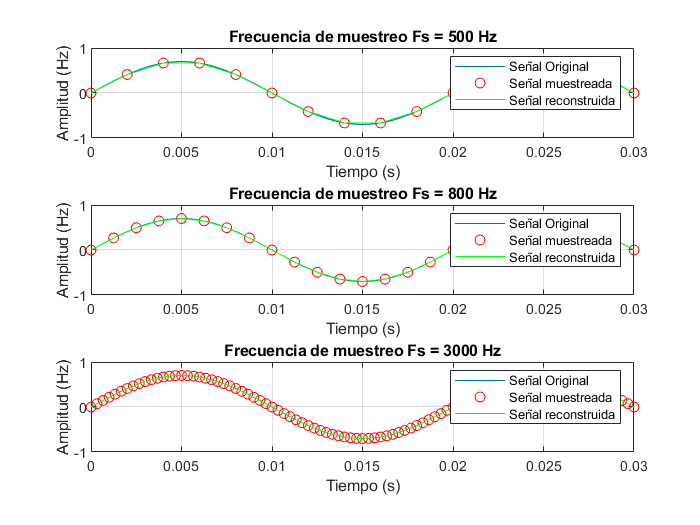

close all
figure(8);
%% 500Hz
k = k500;
subplot(3,1,1); fplot(y1,[0,0.03]); hold on; 
plot(k,Y1,'ro'); plot(k,Y1,'g-'); axis([0 0.03 -1 1])
title('Frecuencia de muestreo Fs = 500 Hz')
legend('Señal Original','Señal muestreada','Señal reconstruida')
xlabel('Tiempo (s)'); ylabel('Amplitud (Hz)');
grid on
%% 800 Hz
k = k800;
subplot(3,1,2); fplot(y4,[0,0.03]); hold on; 
plot(k,Y4,'ro'); plot(k,Y4,'g-'); axis([0 0.03 -1 1])
title('Frecuencia de muestreo Fs = 800 Hz')
legend('Señal Original','Señal muestreada','Señal reconstruida')
xlabel('Tiempo (s)'); ylabel('Amplitud (Hz)');
grid on
%% 3000Hz
k = k3000;
subplot(3,1,3); fplot(y7,[0,0.03]); hold on; 
plot(k,Y7,'ro'); plot(k,Y7,'g-'); axis([0 0.03 -1 1])
title('Frecuencia de muestreo Fs = 3000 Hz')
legend('Señal Original','Señal muestreada','Señal reconstruida')
xlabel('Tiempo (s)'); ylabel('Amplitud (Hz)');
grid on

Segunda componente:

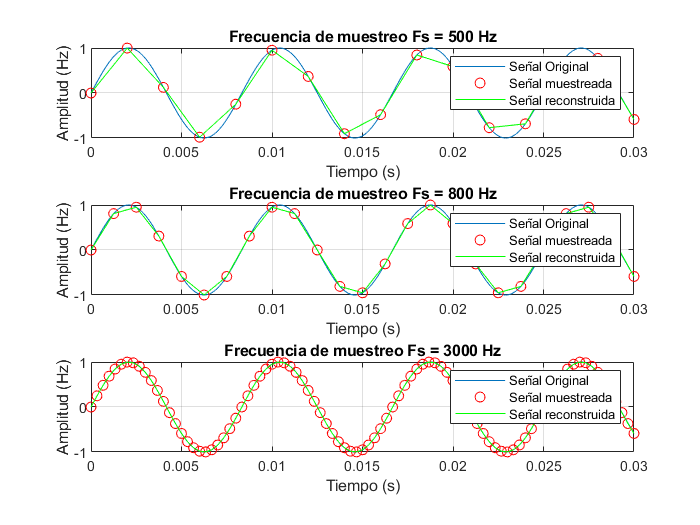

figure(9);
%% 500Hz
k = k500;
subplot(3,1,1); fplot(y2,[0,0.03]); hold on; 
plot(k,Y2,'ro'); plot(k,Y2,'g-'); axis([0 0.03 -1 1])
title('Frecuencia de muestreo Fs = 500 Hz')
legend('Señal Original','Señal muestreada','Señal reconstruida')
xlabel('Tiempo (s)'); ylabel('Amplitud (Hz)');
grid on
%% 800 Hz
k = k800;
subplot(3,1,2); fplot(y5,[0,0.03]); hold on; 
plot(k,Y5,'ro'); plot(k,Y5,'g-'); axis([0 0.03 -1 1])
title('Frecuencia de muestreo Fs = 800 Hz')
legend('Señal Original','Señal muestreada','Señal reconstruida')
xlabel('Tiempo (s)'); ylabel('Amplitud (Hz)');
grid on
%% 3000Hz
k = k3000;
subplot(3,1,3); fplot(y8,[0,0.03]); hold on; 
plot(k,Y8,'ro'); plot(k,Y8,'g-'); axis([0 0.03 -1 1])
title('Frecuencia de muestreo Fs = 3000 Hz')
legend('Señal Original','Señal muestreada','Señal reconstruida')
xlabel('Tiempo (s)'); ylabel('Amplitud (Hz)');
grid on

Tercera componente:

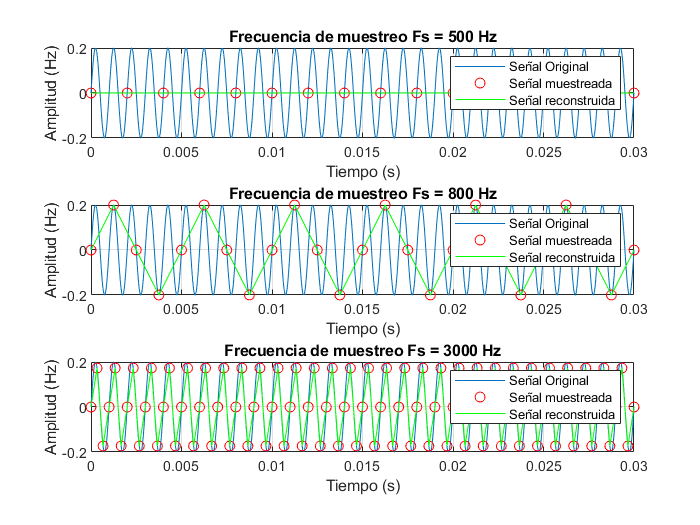

figure(10);
%% 500Hz
k = k500;
subplot(3,1,1); fplot(y3,[0,0.03]); hold on; 
plot(k,Y3,'ro'); plot(k,Y3,'g-'); axis([0 0.03 -0.2 0.2])
title('Frecuencia de muestreo Fs = 500 Hz')
legend('Señal Original','Señal muestreada','Señal reconstruida')
xlabel('Tiempo (s)'); ylabel('Amplitud (Hz)');
grid on
%% 800 Hz
k = k800;
subplot(3,1,2); fplot(y6,[0,0.03]); hold on; 
plot(k,Y6,'ro'); plot(k,Y6,'g-'); axis([0 0.03 -0.2 0.2])
title('Frecuencia de muestreo Fs = 800 Hz')
legend('Señal Original','Señal muestreada','Señal reconstruida')
xlabel('Tiempo (s)'); ylabel('Amplitud (Hz)');
grid on
%% 3000Hz
k = k3000;
subplot(3,1,3); fplot(y9,[0,0.03]); hold on; 
plot(k,Y9,'ro'); plot(k,Y9,'g-'); axis([0 0.03 -0.2 0.2])
title('Frecuencia de muestreo Fs = 3000 Hz')
legend('Señal Original','Señal muestreada','Señal reconstruida')
xlabel('Tiempo (s)'); ylabel('Amplitud (Hz)');
grid on

## Observaciones

Se puede observar la importancia de la eleccion de la frecuencia de muestreo.

Es una eleccion no trivial

Se puede cometer fallo tanto al elegir una frecuenia baja como muy alta.